# **	Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

**Nombre:**

**Fecha:**

# Tema 4. Ejercicio 3 - Transformada de Fourier

El objetivo de la práctica es calcular la transformada de Fourier de todos los objetos de una imagen y utilizar sólo las componentes más significativas de cada objeto para reconstruirlos.

Step 1) Read Image

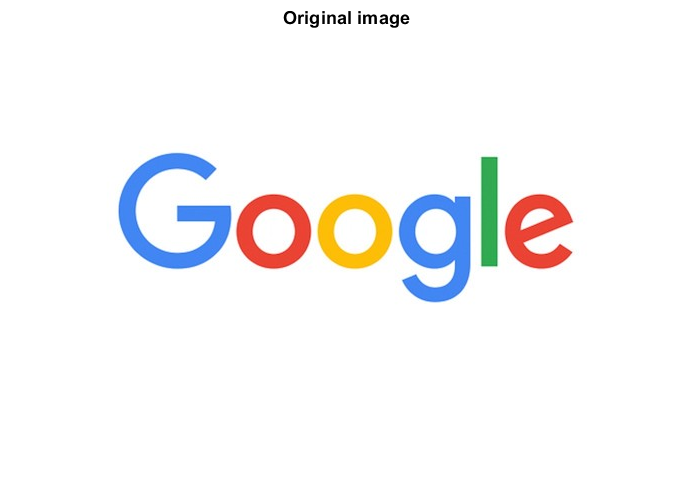

    close all
    clear all

    imgOriginal = imread('google.jpg');
    figure;
    imshow(imgOriginal);
    title('Original image');

Step 2) Threshold the Image

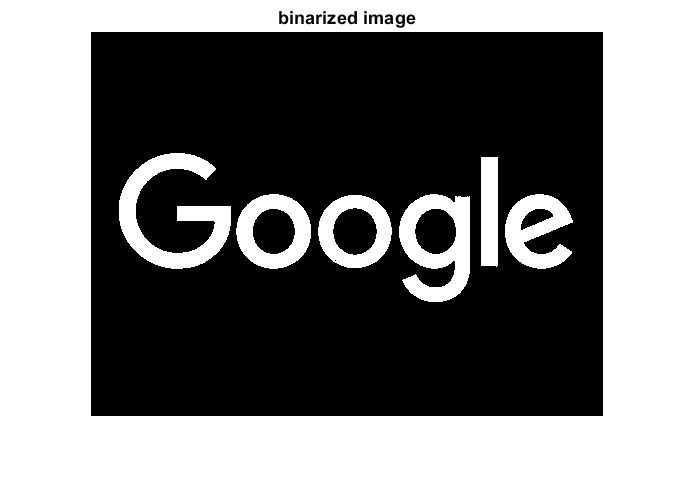

    if size(imgOriginal,3) == 3
        imgOriginal = rgb2gray(imgOriginal); 
    end
    imgBW = imbinarize(imgOriginal);
    imgBW = imcomplement(imgBW);
    
    figure;
    imshow(imgBW);
    title('binarized image');

Step 4) Find the external Boundaries

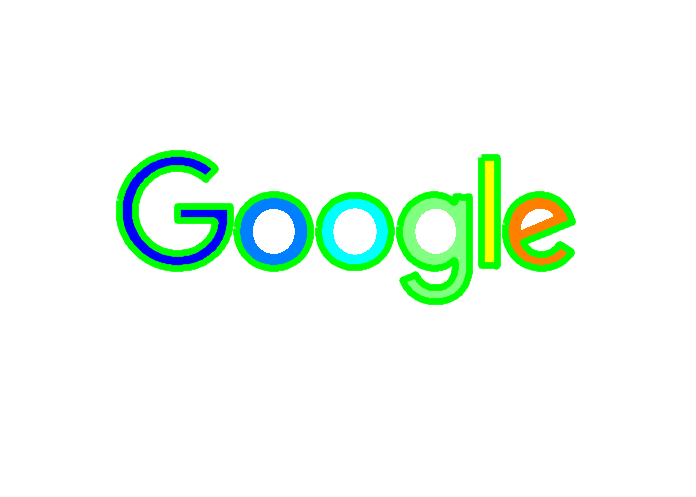

    [B,L] = bwboundaries(imgBW,'noholes');
    figure
    imshow(label2rgb(L, @jet, [1.0 1.0 1.0]))
    hold on
    for k = 1:length(B)
       boundary = B{k};
       plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 4);
    end  

Step 5)  Fourier transform 

     
    for k = 1:length(B)
       boundary = B{k};
       % fourier_transform()    %  a partir de las boundaries
                                % proporciona la transformada de Fourier
                                % (listado de números complejos)
       
       % fourier_inv_transform()   %  a partir de un número determinado de componentes de
                                   % la transformada de Fourier recupera las boundaries aproximadas
       
       % plot recovered boundary
       
    end   

Se pide: 

- Complete el paso 5, utilizando la función `fourier_transform(),` proporcionada con este enunciado, para obtener la transformada de Fourier de cada uno de los objetos etiquetados.

- Obtenga los contornos reconstruidos de los objetos etiquetados utilizando realizando la transformada inversa de Fourier con la función **fourier_inv_transform()**, también incluida con el enunciado. Utilice el 10% de las componentes para la reconstrucción y dibuje el contorno recuperado.

- Reduzca el número de componentes utilizados para la reconstrucción a 5% y 2% y explique sus conclusiones.